# Inner Controller Identification

## Plant Model:

This model should be correct. The parameters are good, the output it produces lines up with what I foudn in the thesis.

Iyy  =  34.7e-3;  % kg m^2
dM_q = -46.3e-3;  % N m s
dM_u =  15e-3;    % Nms

A = [
    1 / Iyy * dM_q,  0;
    1                0;
];

B = [1 / Iyy * dM_u; 0];
C = [1 0];
D = 0;

PitchRateModel = ss(A, B, C, D, ...
    'InputName', 'Delta Omega', 'OutputName', 'Pitch Rate (q)');
    
Mixer = dM_u^-1;

PlantModel = PitchRateModel * Mixer;

## Controller (PID

There was some confusion over the parameters of the inner controller initially but these should be the correct values.

Controller = pid(.3, .3, .05, .01);

## Reference Model. 

In this bastardised version of VRFT we use the compl. sensitivity of the loop to build the reference model.

cloop = loopsens(PlantModel, Controller);
ReferenceModel = cloop.Ti;

We need to discretize these models to do anything.

Ts = .01;
    
PlantModel_dt     = c2d(tf(PlantModel), Ts);
ReferenceModel_dt = c2d(tf(ReferenceModel), Ts);

## VRFT Time with PRBS

First we make the I/O data

% I/O Signals
N = 2000;
time = [0:(N-1)] * Ts;

% The parameters used here are the same used in the other scripts
u = idinput(N, 'prbs', [0 .015], [-.15, .15]);

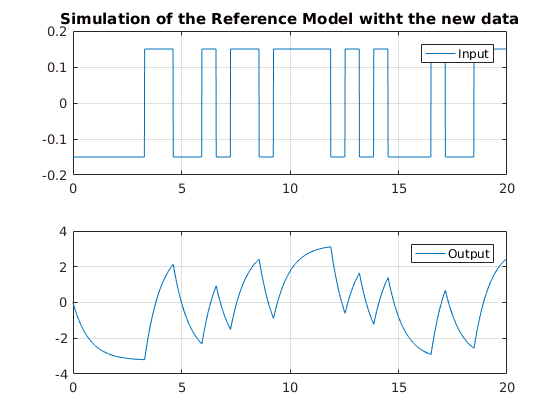

y = lsim(PlantModel_dt, u, time);

figure()
    subplot 211
        plot(time, u); legend('Input')
        title('Simulation of the Reference Model witht the new data');
    subplot 212 
        plot(time, y), legend('Output')

The controller class:

ControllerClass = [ 1, tf(1, [1 0]), tf([1 0], [.01 1]) ].';
ControllerClass_dt = c2d(ControllerClass, Ts);

And run the VRFT engine.

Note: `VRFT1_ry_theta` is an extension of the `VRFT1_ry` method that also exposes the value of the parameter vector. The only changes from the original file are related to this. 

[OptimalController, Theta] = ...
    VRFT1_ry_theta(u, y, ReferenceModel_dt, ControllerClass_dt, [], [], []);

fprintf('The optimal PID parametters for the inner controller are: \n');

The optimal PID parametters for the inner controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', Theta(1), Controller.Kp);

Kp = +0.577013, Original: 0.3    


fprintf('Ki = %+7g, Original: %-7g\n', Theta(2), Controller.Ki);

Ki = -0.0370861, Original: 0.3    


fprintf('Kd = %+7g, Original: %-7g\n', Theta(3), Controller.Kd);    

Kd = +0.012893, Original: 0.05   



cloop = loopsens(PlantModel_dt, OptimalController); 

disp('#==============')

#==============


disp('Compl. Sensitivity with OptimalController:')

Compl. Sensitivity with OptimalController:


tf(cloop.Ti)


ans =
 
  From input "du" to output "uC":
    0.5343 z^2 - 0.9642 z + 0.4299
  -----------------------------------
  z^3 - 1.82 z^2 + 0.7534 z + 0.06689
 
Sample time: 0.01 seconds
Discrete-time transfer function.



disp(' ')

disp('Reference Model:')

Reference Model:


ReferenceModel_dt


ReferenceModel_dt =
 
  From input "du" to output "uC":
     0.5672 z^2 - 1.103 z + 0.5358
  -----------------------------------
  z^3 - 2.042 z^2 + 1.121 z - 0.07881
 
Sample time: 0.01 seconds
Discrete-time transfer function.



disp('#==============')

#==============


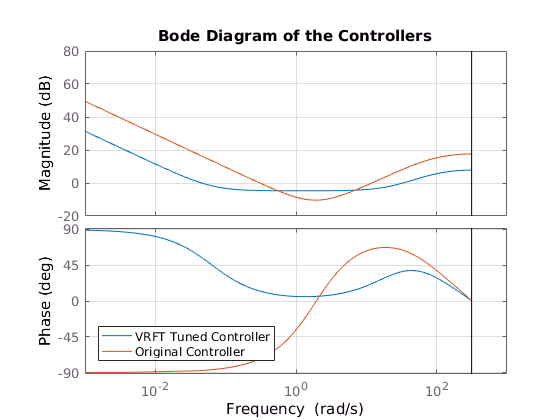


figure()
    bode(OptimalController, c2d(Controller, Ts));
    title('Bode Diagram of the Controllers'); 
    legend('VRFT Tuned Controller', 'Original Controller', 'location', 'SouthWest');
    grid on;

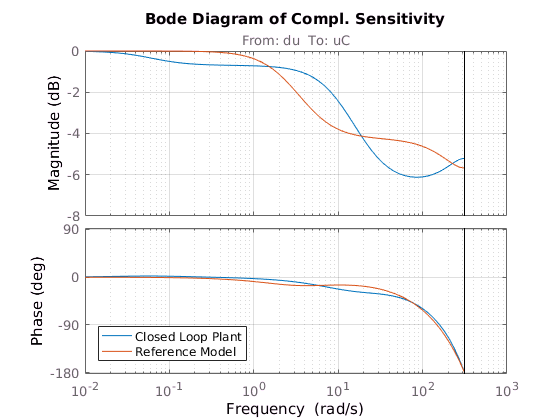


figure()
    bode(cloop.Ti, ReferenceModel_dt);
    title('Bode Diagram of Compl. Sensitivity');
    legend('Closed Loop Plant', 'Reference Model', 'location', 'SouthWest');
    grid on;

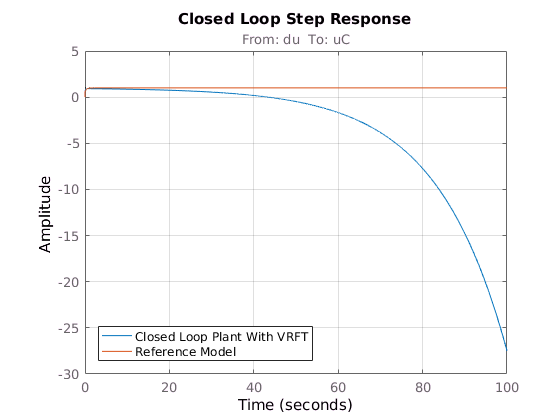

    
figure()
    step(cloop.Ti, ReferenceModel_dt);
    title('Closed Loop Step Response');
    legend('Closed Loop Plant With VRFT', 'Reference Model', 'location', 'SouthWest');
    grid on;    